## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from PDE model with Reflecting boundaries |x|<=a.

This scrip just changing para by hand and make the frame of simulation.

## fv01 Intro

we want to plot curves with different para.

## Import data and previewing

The data come from expomential fitness data.

data_name='p47';
selecting_curve='xy';
experiment_interval=5;
min_length=51;
time_scale=experiment_interval*(1:min_length);

fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=1.046e+05;%p47_5s
a(2)=0.0004364;
a(3)=-7.307e+04;
a(4)=-0.03125;

Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);


## Parameter importing

range_a=5e-7:5e-8:7e-7;%m
range_Gamma=0.5;%[0.4,0.5,0.6,0.8,1];
range_K_gamma=1e-14;%[3e-15,5e-15,10e-15,25e-15,625e-15];
figure

## Main loop

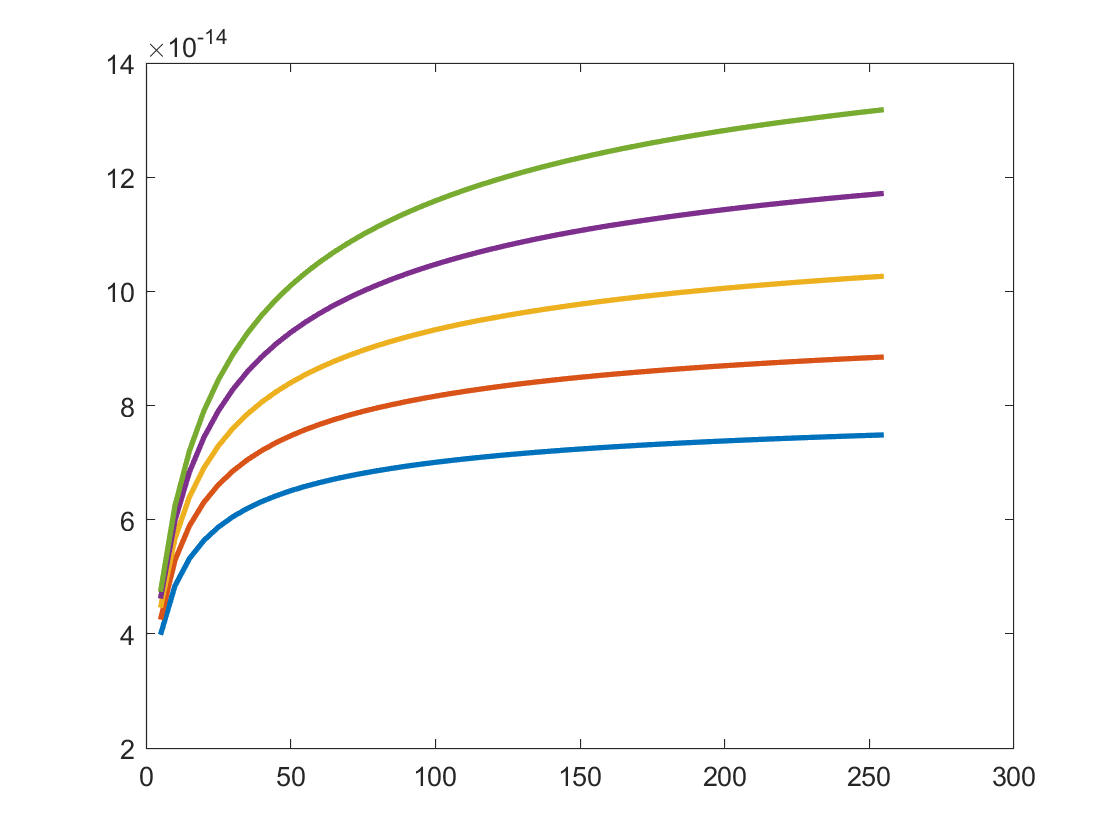

for a=range_a
    for Gamma=range_Gamma
        for K_gamma=range_K_gamma
            simulation_MSD=[];
            for t=experiment_interval*[1:min_length]
                sum_number=10;
                sum_list=zeros(sum_number,1);
                for m=1:sum_number
                    sum_list(m)=((-1)^m/m^2)*mlf(Gamma,1,-K_gamma*m^2*pi^2/a^2*t^Gamma,6);
                end
                simulation_MSD=[simulation_MSD,a^2*(1/3+4/pi^2*sum(sum_list))];
            end
            legend_name=strcat(' a= ',num2str(a),'m \gamma=',num2str(Gamma),' K_\gamma= ',num2str(K_gamma));
            plot(time_scale,simulation_MSD,'DisplayName',legend_name,'LineWidth',2);
            hold on
        end
    end
end

## Plot and saving

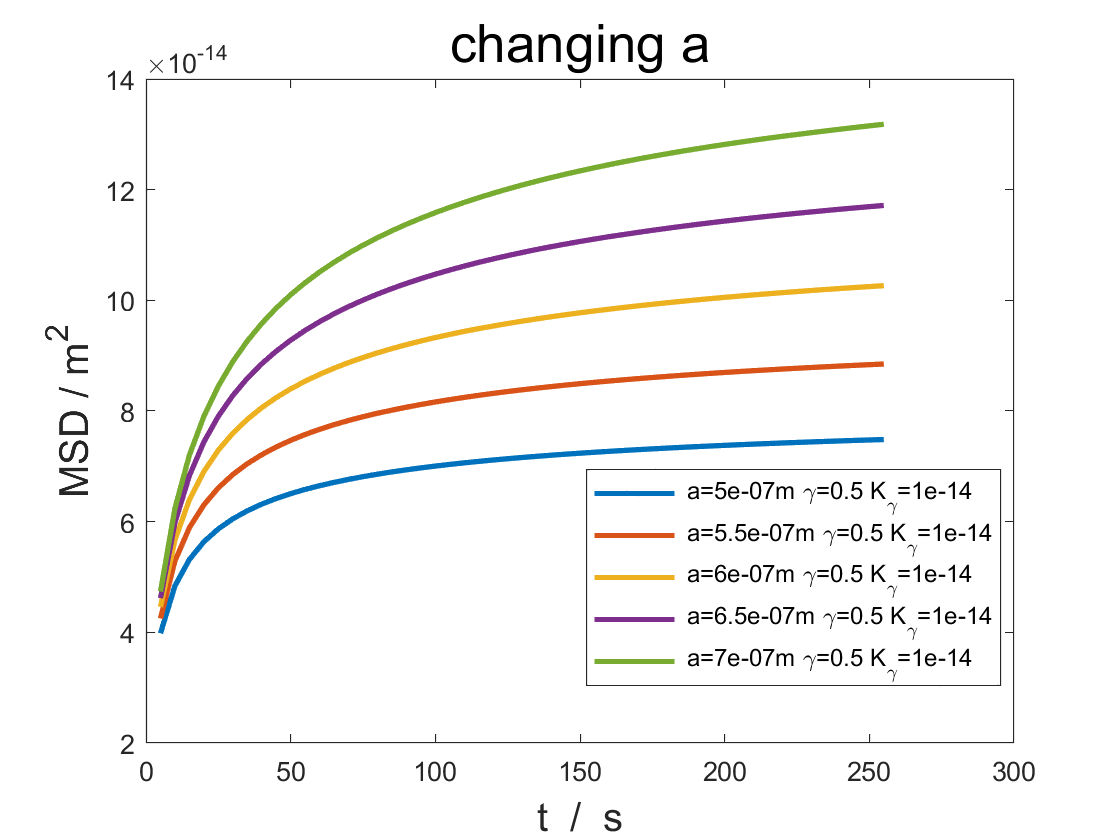

xlabel('t  /  s','FontSize',15);
ylabel('MSD / m^2','FontSize',15);
title({'changing a'},'FontSize',20);
legend('Location','best');

## Saving

%storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.04图像';
%saveas(gcf,strrep([storage_location,'\image\FDE-MSD','.a=',num2str(a),'.Gamma=',num2str(Gamma),'.K_gamma=',num2str(K_gamma),'.jpg'],'       ',' '))
